**PREWITT**

Using Averaging with Derivatives  (slide 569)

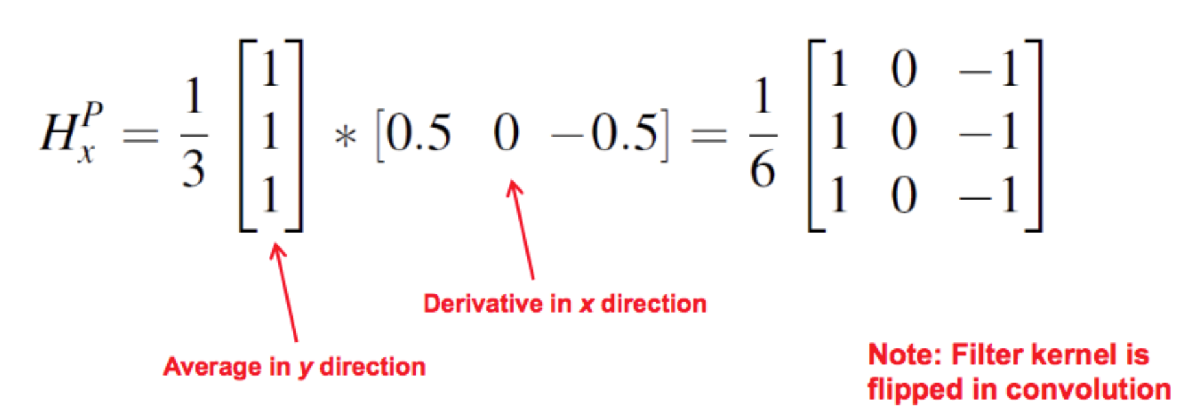

clear
close all
a=imread('coins.png');
w=[-1 0 1;-1 0 1;-1 0 1];
an=imnoise(a,'gaussian');
an=double(an);
bn=imfilter(an,w);
wd=[-0.5 0 0.5];
bd=imfilter(an,wd);
subplot(1,2,1)
imshow(mat2gray(bn))
title('Prewit')
subplot(1,2,2)
imshow(mat2gray(bd))
title('central difference')

h=**fspecial**('prewitt');   horizontal kernel

h' vertical kernel     

clear
close all
a=imread('coins.png');
wp1=fspecial('prewitt');
fp_h=imfilter(a,wp1./6);
fp_v=imfilter(a,wp1'./6);
figure
subplot(2,3,1)
imshow(a)
subplot(2,3,2)
imshow(mat2gray(fp_h))
title('horizontal edges')
subplot(2,3,3)
imshow(mat2gray(fp_v))
title('vertical edges')
% add noise
an=imnoise(a,'gaussian',0.08);
an=double(an);
fp_nh=imfilter(an,wp1./6);
fp_nv=imfilter(an,wp1'./6);
subplot(2,3,4)
imshow(mat2gray(an))
subplot(2,3,5)
imshow(mat2gray(fp_nh))
title('horizontal edges')
subplot(2,3,6)
imshow(mat2gray(fp_nv))
title('vertical edges')

Derivatives  VS PREWITT 

clear
close all
a=imread('coins.png');
w=[-1 0 1;-1 0 1;-1 0 1];
an=imnoise(a,'gaussian',0,0.003);
bn=imbinarize(imfilter(an,w));
wd=[-0.5 0 0.5];
bd=imbinarize(imfilter(an,wd));
imshowpair(bn, bd, 'montage');

**SOBEL  **slide 575

**similar to Prewit  but averaging kernel is higher in the middle**

The size of the convolution kernels can be increased to improve robustness to noise.

clear
close all
a=imread('coins.png');
an=imnoise(a,'gaussian',0,0.002);
an=double(an);
w=[0.5 0 -0.5];
fd=imfilter(an,w');
subplot(2,2,1)
imshow(mat2gray(fd));
title('derivative');
wp1=fspecial('prewitt');
fp=imfilter(an,wp1./6);
wp2=fspecial('sobel');
fp2=imfilter(an,wp2./8);
subplot(2,2,2)
imshow(mat2gray(fp));
title('prewitt');
subplot(2,2,3)
imshow(mat2gray(fp2));
title('sobel');
z=zeros(7);
z(1:3,:)=1;
z(5:7,:)=-1;
fp3=imfilter(an,z./42);
subplot(2,2,4)
imshow(mat2gray(fp3));
title('prewitt 7*7');

**Improving robustness to noise **(slide 581 - 586)

Numerical derivatives can amplify noise

Combining smoothing with differentiation

– Solution 1: do smoothing first and then differentiation

– Solution 2: differentiate the smoothing filter and do filtering

**Derivative of a Gaussian **

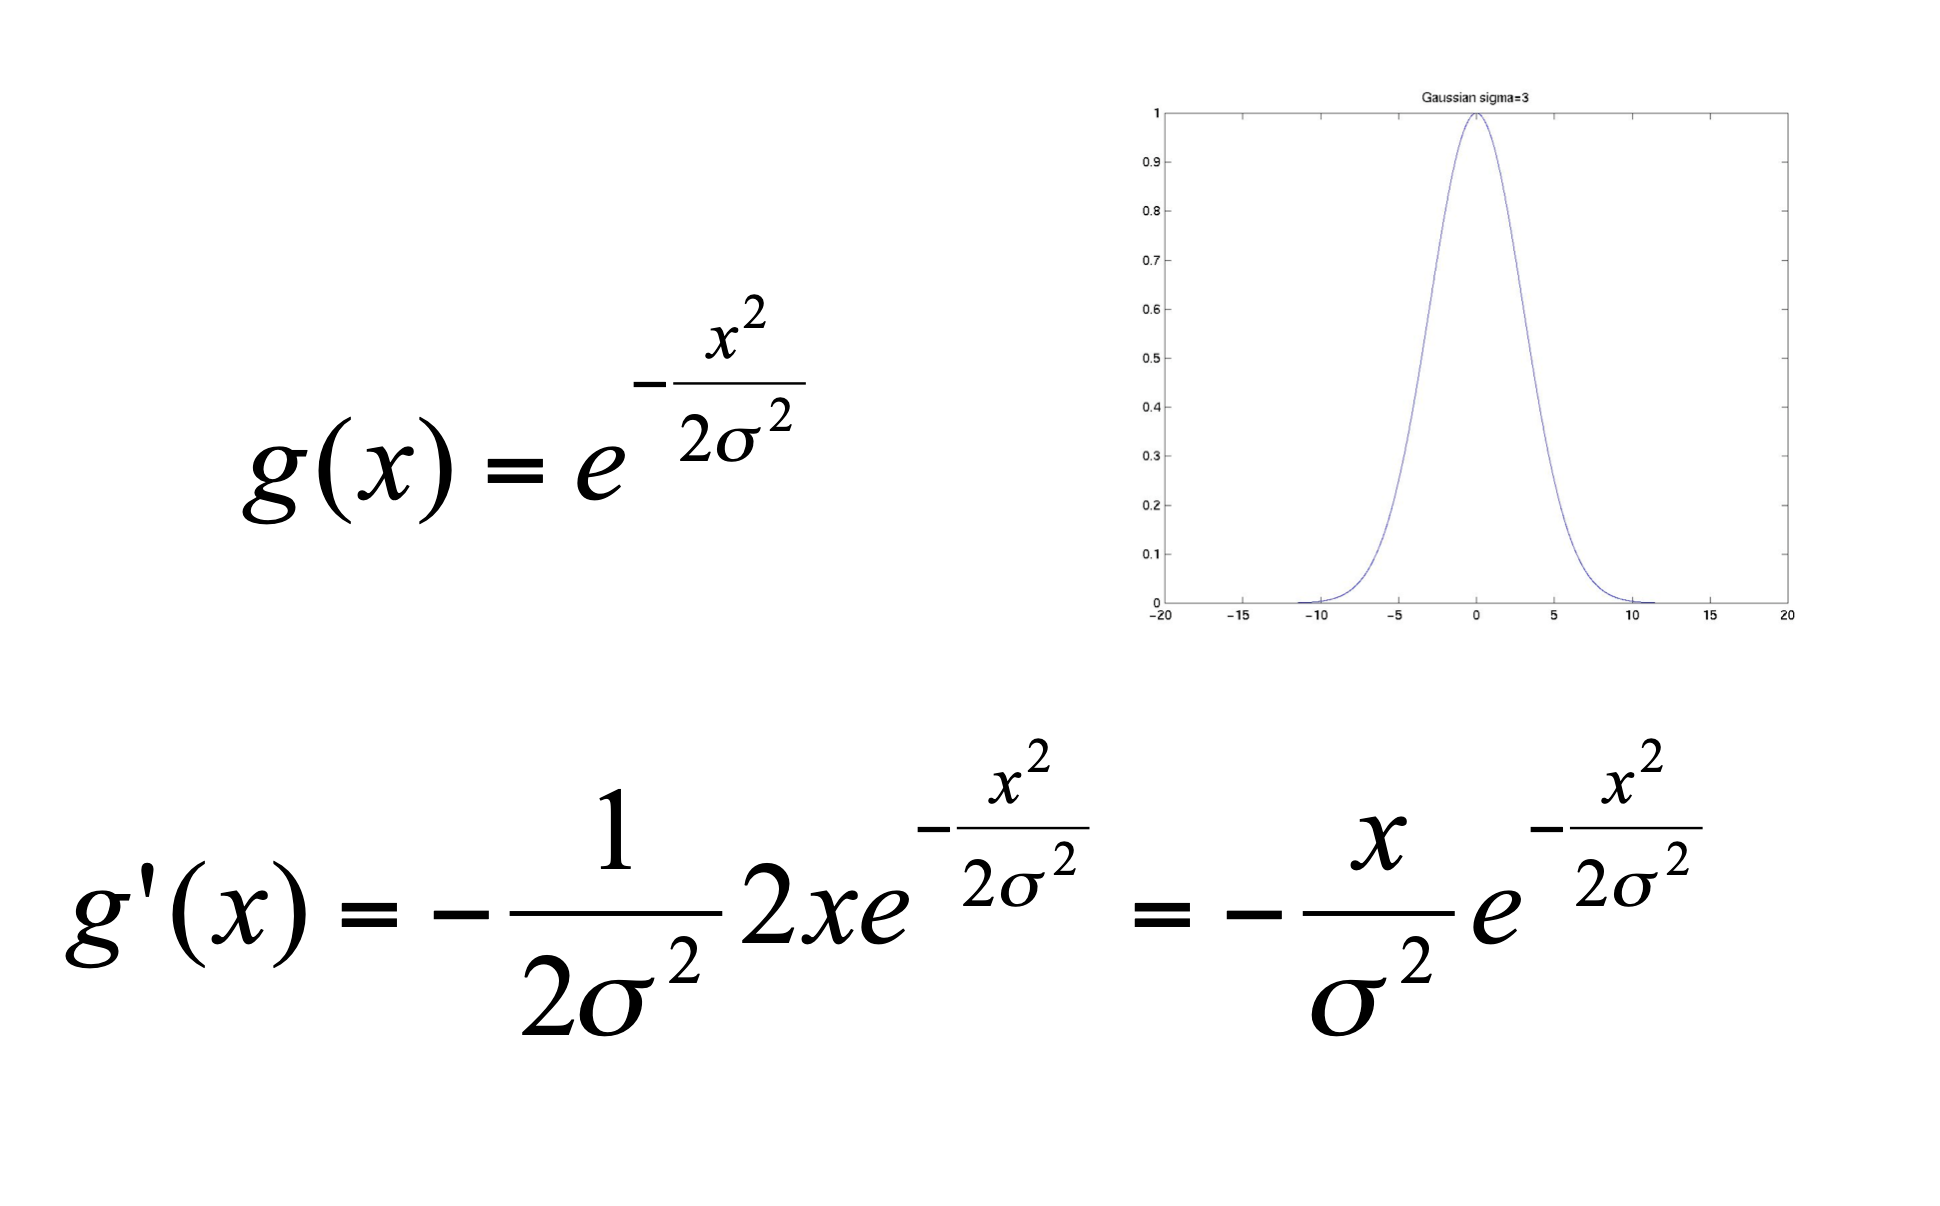

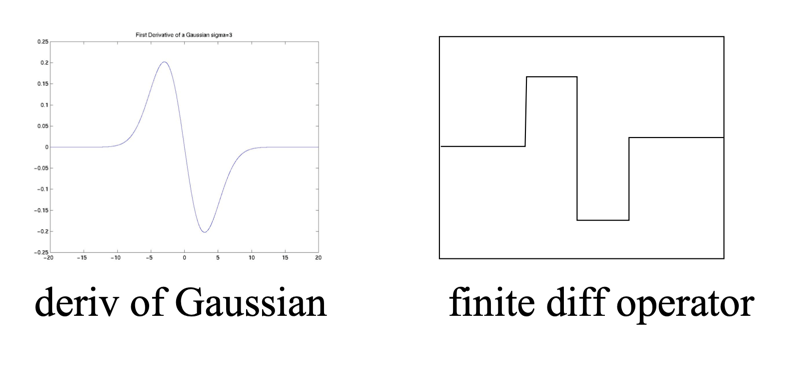

`[`[`FX`](https://it.mathworks.com/help/releases/R2024b/matlab/ref/gradient.html?searchHighlight=gradient&s_tid=doc_srchtitle#bvhp5on-FX)`,`[`FY`](https://it.mathworks.com/help/releases/R2024b/matlab/ref/gradient.html?searchHighlight=gradient&s_tid=doc_srchtitle#bvhp5on-FX)`] =` `gradient``(`[`F`](https://it.mathworks.com/help/releases/R2024b/matlab/ref/gradient.html?searchHighlight=gradient&s_tid=doc_srchtitle#bvhp5on-F)`)` returns the *x* and *y* components of the two-dimensional [numerical gradient](https://it.mathworks.com/help/releases/R2024b/matlab/ref/gradient.html#bvhp8_m) of matrix `F`. The additional output `FY` corresponds to ∂*F*/∂*y*, which are the differences in the *y* (vertical) direction. The spacing between points in each direction is assumed to be `1`.

clear
close all
a=imread('R2.jpg');
a=rgb2gray(a);
a=imresize(a,0.2);
a2=double(a);
f=fspecial('gauss',11,2);
[Gx,Gy] = gradient(f); 
ax=imfilter(a2,Gx);
ay=imfilter(a2,Gy);
subplot(1,2,1)
imshow(ax)
title ('Derivative of a Gaussian x')
subplot(1,2,2)
imshow(ay)
title ('Derivative of a Gaussian y')
colormap(gray);

figure
subplot(1,2,1)
mesh(Gx)
title('dog x')
subplot(1,2,2)
mesh(Gy)
title('dog y')

**Derivative of a Gaussian on a noisy image**

clear
close all
a=imread('R2.jpg');
a=rgb2gray(a);
a=imresize(a,0.2);
a=imnoise(a,'gaussian',0,0.002);
a2=double(a);
% filtering by derivative of a gaussian
f=fspecial('gauss',11,2);
[Gx,Gy] = gradient(f); 
ax=imfilter(a2,Gx);
% filtering by central difference
w=[-0.5 0 0.5];
ay=imfilter(a2,w);
subplot(1,2,1)
imshow(ax)
title ('Derivative of a Gaussian x')
subplot(1,2,2)
imshow(ay)
title ('central difference')
colormap(gray);

**Laplacian filter **

slide 587

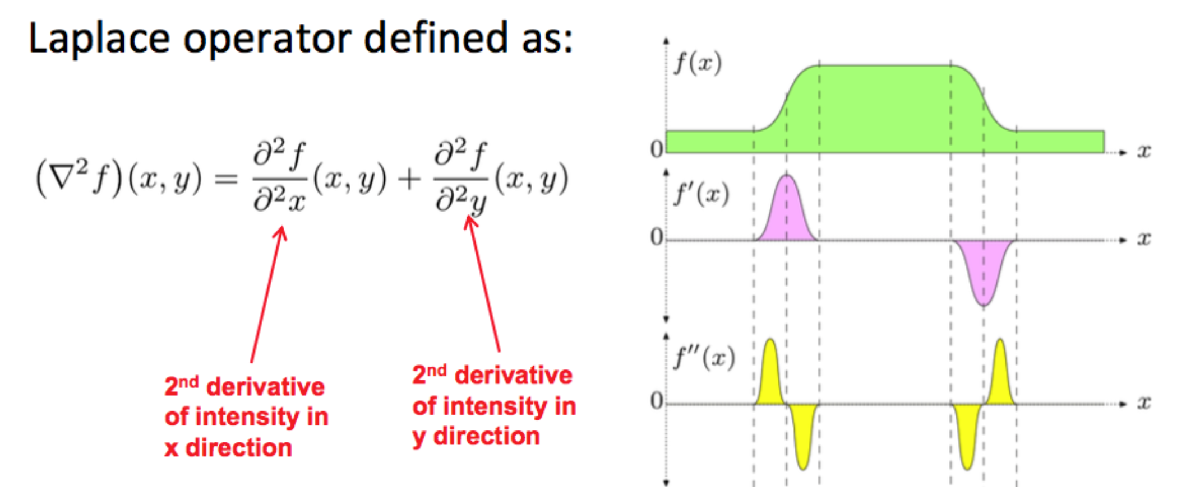

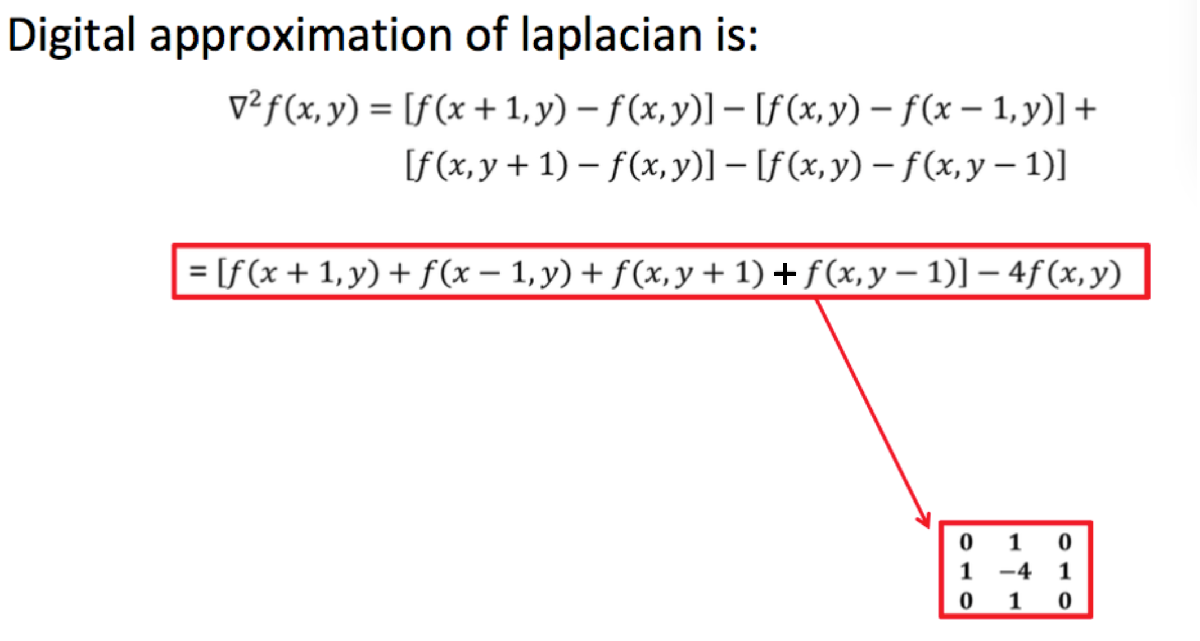

clear
close all
f=imread('moon.tif');
w4=fspecial('laplacian', 0);
w8=[1 1 1; 1 -8 1; 1 1 1];
f=im2double(f);
g4= imfilter(f, w4, 'replicate');
g8=imfilter(f, w8, 'replicate');
imshow(mat2gray(f)); 
figure, imshow(mat2gray(abs(g4)));
title('W4')
figure, imshow(mat2gray(abs(g8)))
title('W8')

Numerical derivatives can amplify noise

Smooth by a gaussian filter before applying the Laplacian filter. 

[`h`](https://it.mathworks.com/help/images/ref/fspecial.html#d126e119373) `= ``fspecial``('log',`[`hsize`](https://it.mathworks.com/help/images/ref/fspecial.html#d126e119191)`,`[`sigma`](https://it.mathworks.com/help/images/ref/fspecial.html#d126e119262)`)` 

returns a rotationally symmetric Laplacian of Gaussian filter of size `hsize` with standard deviation `sigma`.

h=fspecial('log',101,5);
mesh(h)

**LOG**

[`h = fspecial('log',hsize,sigma)`](https://it.mathworks.com/help/images/ref/fspecial.html#d126e118921)

clear
close all
f=imread('moon.tif');
f=im2double(f);
f=imnoise(f,'gaussian',0,0.001);
w4=fspecial('laplacian', 0);
g4= imfilter(f, w4, 'replicate');
log=fspecial('log',7,1);
LOG= imfilter(f, log, 'replicate');
subplot(1,3,1)
imshow(mat2gray(f)); 
subplot(1,3,2)
imshow(mat2gray(abs(g4)));
title('laplacian')
subplot(1,3,3)
imshow(mat2gray(abs(LOG)))
title('LoG')

**Imgradient** slide 594

[Gx,Gy] = **imgradientxy**(I,`method`) returns the directional gradients

`method` `sobel` (default) ; prewitt

[Gmag, Gdir] = **imgradient**(Gx, Gy)

calculates the gradient magnitude and direction from the directional gradients

**Exercise**:

Read coins.png 

Show Directional Gradients Gx and Gy (Sobel)

Use Gx and Gy (Sobel) to evaluate Gradient Magnitude and Gradient Direction

Evaluate Gradient Magnitude and Gradient Direction (Prewitt method)

Show difference between Sobel-Prewitt

clear
close all
I = imread('coins.png');
figure
subplot(2,2,1)
[Gx,Gy] = imgradientxy(I,'sobel');
imshowpair(Gx,Gy,'montage')
title('Directional Gradients Gx and Gy, Using Sobel Method')


subplot(2,2,2)
[Gmag,Gdir] = imgradient(Gx,Gy);
imshowpair(Gmag,Gdir,'montage')
title('Gradient Magnitude and Gradient Direction (Sobel)')


[Gmagp, Gdirp] = imgradient(I,'prewitt');
subplot(2,2,3)

imshowpair(Gmagp, Gdirp, 'montage');
title('Gradient Magnitude, Gmag (left), and Gradient Direction, Gdir (right), using Prewitt method')
subplot(2,2,4)

a=Gmag-Gmagp;
b=Gdir-Gdirp;
imshowpair(a, b, 'montage');
title('Difference (Sobel - Prewitt) Magnitude and  Direction')

**Exercise**:

Read yellowlily.jpg 

Add gaussian noise

Show gradient magnitude 

Smooth the noisy image by imgaussfilt

show gradient magnitude of smoothed image

clear
close all
originalImage = imread('yellowlily.jpg');
originalImage = rgb2gray(originalImage);
subplot(2,2,1)
imshow(originalImage)
title('original image')
noisyImage = imnoise(originalImage,'gaussian');
subplot(2,2,2)
imshow(noisyImage)
title('noisy image')
[Gmag,Gdir] = imgradient(noisyImage);
subplot(2,2,3)
imshow(Gmag,[])
title('Sobel Gradient Magnitude')
sigma = 2;
smoothImage = imgaussfilt(noisyImage,sigma);
smoothGradient = imgradient(smoothImage,'CentralDifference');
subplot(2,2,4)
imshow(smoothGradient,[])
title('Smoothed Gradient Magnitude')

BW = **edge**(I,'Sobel',threshold,direction) **slide 599**

**direction**: specify the direction in which the function looks for edges in the image: **'horizontal', 'vertical', or 'both'.**

**threshold** value  determines the magnitude of the gradient to consider as an edge. A threshold value of `0` selects all edges in the image, even if they have very low strength.

example:

consider an image that represents a square.

clear
close all
im=zeros(100); 
im(26:74,26:74)=1;
imagesc(im); 
colormap gray;
% edge by gradient (sobel)
[Gx,Gy] = imgradientxy(im,'sobel');
figure
mesh(Gx)
figure
mesh(Gy)
% To obtain the module of the gradient, 
% in all directions:
% im_mod_grad=sqrt(im_sob_x.^2+im_sob_y.^2);
BW1 = edge(im,'Sobel');
figure
imagesc(BW1)
colormap(gray)

**Image Sharpening  by Laplacian filter** slide 604

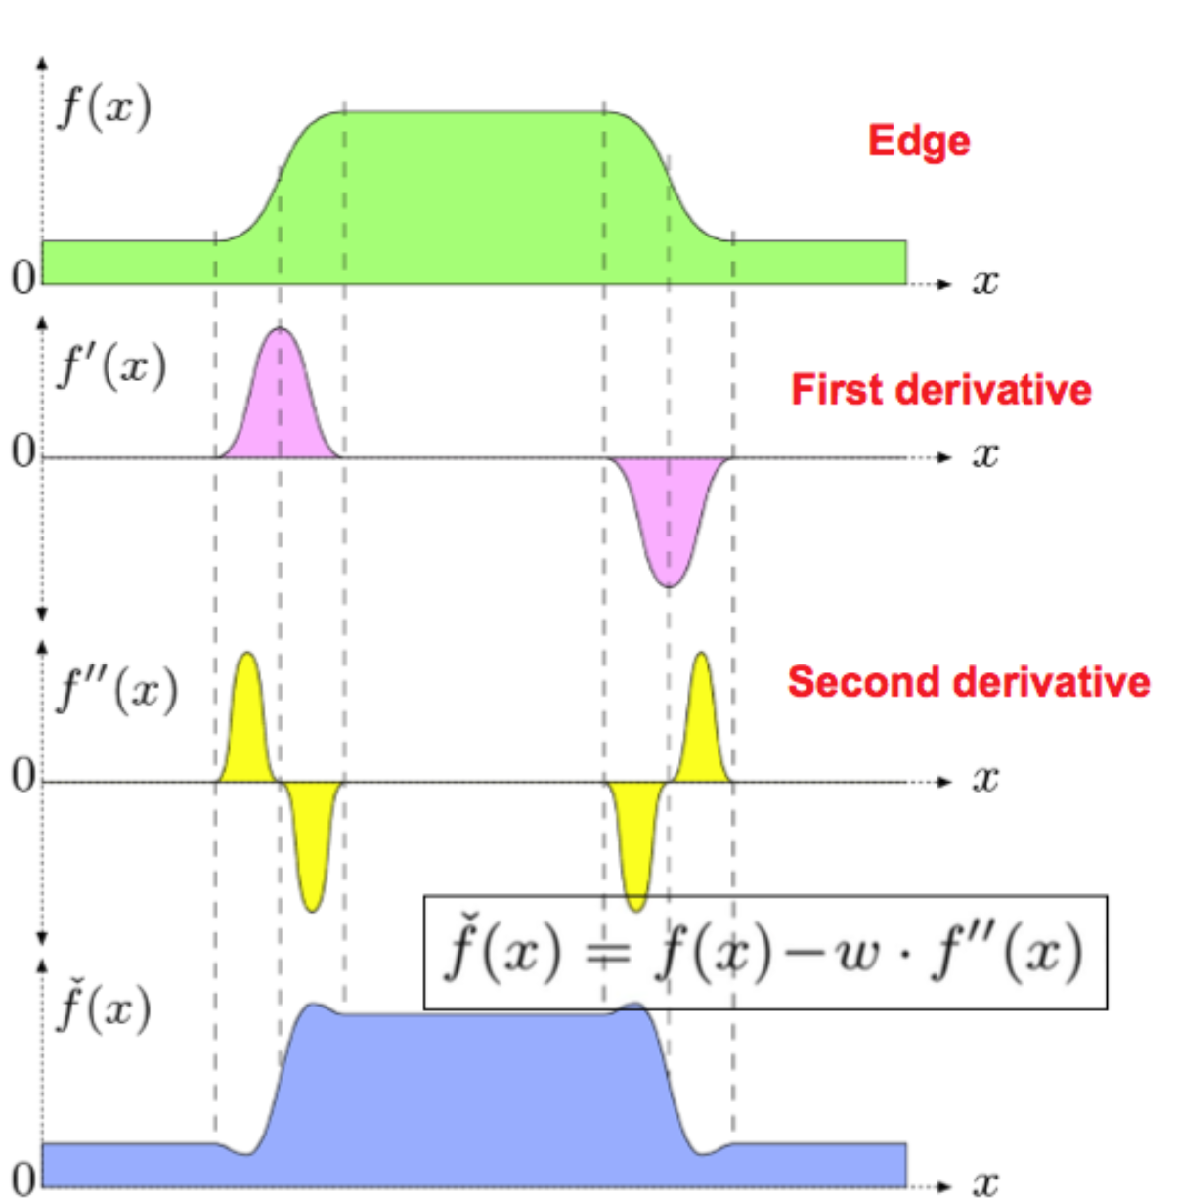

Laplacian kernel

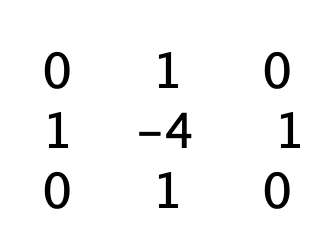           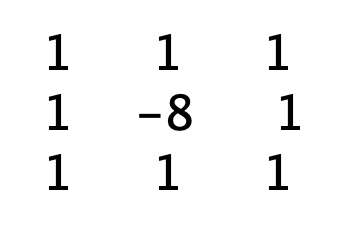

sharper image = image - laplacian (if central coefficient is < 0)

sharper image = image + laplacian (if central coefficient is > 0)

clear
close all
a=imread('moon.tif');
subplot(1,3,1)
image(a)
colormap(gray)
title('input image')
aa=double(a);
w=fspecial('laplacian',0);
g=imfilter(aa,w,'replicate');
subplot(1,3,2)
image(g)
colormap(gray)
title('laplacian')
b=aa-g;
subplot(1,3,3)
image(b)
colormap(gray)
title('image - laplacian')

**Unsharp Masking (USM) **

Unsharp masking is a widely-used technique in both traditional and digital photography for enhancing image sharpness. In the darkroom, a blurred or "unsharp" copy of the original photo was combined with the original to create a sharper final image.

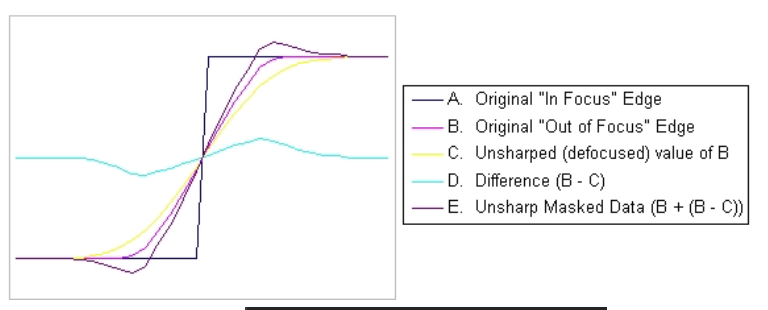

making the bright side of an edge a little bit brighter, and the darker side a little bit darker it improves the micro contrast and the edge steepness, 

The subjective impression of sharpness is significantly improved, without significantly increasing the resolution of detail.

clear
close all
a=imread('lena.jpg');
a=imgaussfilt(a,1);
figure
subplot(2,3,1)
imshow(a)
title('out of focus input image')
b=imgaussfilt(a,2);
subplot(2,3,2)
imshow(b)
title('input image after imgaussfilt')
subplot(2,3,3)
% out of focus image - blurred image
bf=double(a)-double(b);
imshow(mat2gray(bf))
title('input - unsh')
% out of focus image + (out of focus image - blurred image)
fin=double(a)+bf;
subplot(2,3,4)
imshow(mat2gray(fin))
title('unsharped image')
hold on
plot(302,299,'*')
plot(326,299,'*')
v=a(302:326,299);
vu=fin(302:326,299);
subplot(2,3,5)
plot(v)
hold on
plot(vu)
legend('input','USM')

**High boost**

Stronger sharpening by High boost

Combine image with smoothed (blurred) version of image 

HP = O - LP

High boost= A x O - LP

High boost = (A-1) x O + O -LP = (A-1) x O + HP

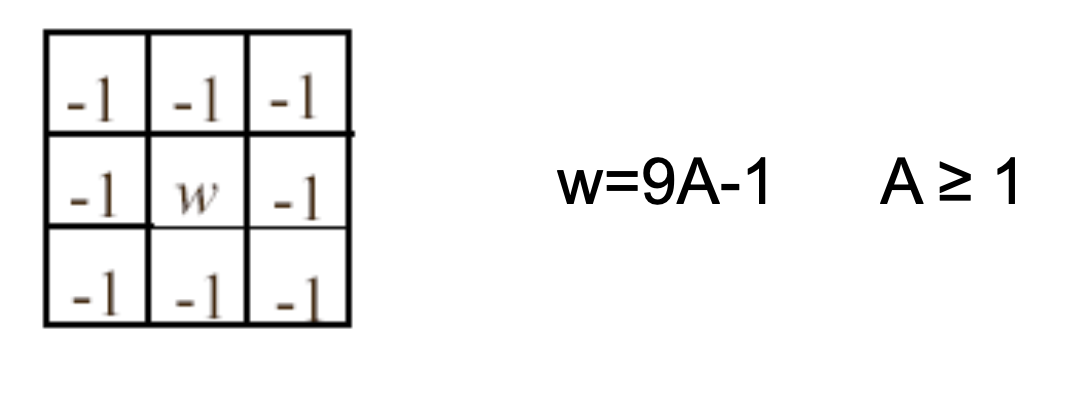

clear
close all
a=imread('R2.jpg');
a=rgb2gray(a);
a=imresize(a,0.2);
A=input('input coefficient A [1:1.2] (w=9A-1) ');
w=9*A-1;
f=[-1 -1 -1;-1 w -1;-1 -1 -1];
b=imfilter(a,f);
imshow(b)

**Matlab Function**

**fspecial**('unsharp',a) 0<a<=1

clear
close all
a=imread('lena.jpg');
% a=imread('R2.jpg');
% a=rgb2gray(a);
% a=imresize(a,0.2);
f=fspecial('unsharp',0.6)
b=imfilter(a,f);
subplot(1,2,1)
imshow(a)
subplot(1,2,2)
imshow(b)
title('fspecial(unsharp)')

[`B`](https://it.mathworks.com/help/releases/R2024b/images/ref/imsharpen.html?searchHighlight=imsharpen&s_tid=doc_srchtitle#btppxju-1-B)` = ``imsharpen``(`[`A`](https://it.mathworks.com/help/releases/R2024b/images/ref/imsharpen.html?searchHighlight=imsharpen&s_tid=doc_srchtitle#btppxju-1-A)`)` sharpens the grayscale or truecolor (RGB) image `A` by using the [unsharp masking](https://it.mathworks.com/help/releases/R2024b/images/ref/imsharpen.html#btupaf8) method.

`b = ``imsharpen``(a,``Radius``=1,``Amount``=0.8);`

`Radius`** — Standard deviation of Gaussian lowpass filter**

`Amount`** — Strength of sharpening effect**

clear
close all
im=imread('coins.png');
imn=imnoise(im,'gaussian',0,0.0004);
subplot(1,2,1)
imshow(imn)
title('im+noise' );
unsharp=imsharpen(imn,Radius=2,Amount=1.2);
subplot(1,2,2)
imshow(unsharp)
title('unsharp');

**Laplacian is sensitive to noise**

image can be first  smoothed with  a Gaussian smoothing filter in order to reduce its sensitivity to noise

Since the convolution operation is associative, we can convolve the Gaussian smoothing filter with the Laplacian filter first of all, and then convolve this hybrid filter with the image

[](https://it.mathworks.com/help/releases/R2024b/images/ref/imsharpen.html?searchHighlight=imsharpen&s_tid=doc_srchtitle#btppxju-1-B)

h=fspecial('log',101,6);
mesh(h)

`b = ``imsharpen``(a,Radius=1,Amount=0.8);`

`Radius`** — Standard deviation of Gaussian lowpass filter**

`Amount`** — Strength of sharpening effect**

Compare:

- laplacian of gaussian

- laplacian

- imsharpen

on a noisy image

clear
close all
im=imread('coins.png');
f=fspecial('log',7,1.2);
imn=imnoise(im,'gaussian',0,0.0004);
subplot(2,2,1)
imshow(imn)
title('im+noise' );
imlog=imfilter(imn,f);
imimlog=imn-imlog;
subplot(2,2,2)
imshow(imimlog)
title('im-log');
f=fspecial('laplacian');
imlap=imfilter(imn,f);
imimlap=imn-imlap;
subplot(2,2,3)
imshow(imimlap)
title('im-lap');
unsharp=imsharpen(imn,Radius=2,Amount=1.2);
subplot(2,2,4)
imshow(unsharp)
title('unsharp');

**Full color image **(slide 639)

color pixels are vectors,

Image N * M pixels => N * M vectors.

The separate processing for each component is possible if: It can be applied to scalar and vector

**Smoothing: **

**RGB => smoothing of each component;**

**HSI => smoothing I component**

clear
close all
rgb = imread('lenac.jpg');
f = ones(5,5)/25;
rgb2 = imfilter(rgb,f);
subplot(2,2,1)
imshow(rgb)
title('original image')
subplot(2,2,2)
imshow(rgb2)
title('smoothed RGB')
hsi=rgb2hsi(rgb);
i=hsi(:,:,3);
i = imfilter(i,f);
hsi(:,:,3)=i;
rgb3=hsi2rgb(hsi);
subplot(2,2,3)
imshow(rgb3)
title('smoothed intensity')
rgb3=uint8(rgb3.*255);
dif=rgb2-rgb3;
subplot(2,2,4)
imshow(10.*dif)
title('difference')

**Sharpening (LAPLACIAN): **

**RGB => sharpening of each component;**

w=fspecial('laplacian',0)

g= imfilter(rgb, w, 'replicate');

g1=rgb-g;

**HSI  => sharpening of intensity;**

hsi=rgb2hsi(rgb);

i=hsi(:,:,3);

is = imfilter(i,w);

hsi(:,:,3)=i-is;

rgb3=hsi2rgb(hsi);

% full color Sharpening (LAPLACIAN): 
% RGB => sharpening of each component;
clear
close all
rgb = imread('lenac.jpg');
% lapmask = [1 1 1; 1 -9 1; 1 1 1];
w=fspecial('laplacian',0)

g= imfilter(rgb, w, 'replicate');
g1=rgb-g;
% f=fspecial('laplacian');
% g= imfilter(rgb, f, 'replicate');

subplot(2,2,1);
imshow(rgb)
title('input image')
subplot(2,2,2);
imshow(g1)
title('image - laplacian')

hsi=rgb2hsi(rgb);
i=hsi(:,:,3);
is = imfilter(i,w);
hsi(:,:,3)=i-is;
rgb3=hsi2rgb(hsi);
subplot(2,2,3)
imshow(rgb3)
title('sharpened intensity')
rgb3=uint8(rgb3.*255);
dif=g1-rgb3;
subplot(2,2,4)
imshow(10.*dif)
title('difference')

**Gradient **(slide 648)

**B&W image**: it can be approximated by the sum of the absolute values of the images obtained with the Sobel filters

Gx = [-1 -2 -1; 0 0 0; 1 2 1]

Gy = [-1 0 1; -2 0 2; -1 0 1]

**Color image**: gradient of a vector?

hsv = rgb2hsv(rgbImage);

hImage = hsv(:,:,1);

sImage = hsv(:,:,2);

vImage = hsv(:,:,3);

processing  v and/or I component

clear
close all
a=imread('lena.jpg');
[g,d]=imgradient(a);
subplot(1,2,1)
imshow(mat2gray(g))
title('lena (grayscale) gradient magnitude')
a=imread("lena_color_256.tif");
aa=rgb2hsi(a);
aa3=imgradient(aa(:,:,3));
subplot(1,2,2)
imshow(mat2gray(aa3));
title('lena color gradient magnitude')

**Point detection**

slide 663

**laplacian filter** to  detected  pixel that are above a threshold 

clear
close all
f=imread('turbine.tif');
subplot(1,3,1)
imshow(f)
T=220;
%laplacian kernel
W = [-1 -1 -1; -1 8 -1; -1 -1 -1]
g=abs(imfilter(double(f), W));
g = g >= T;   %isolated point
subplot(1,3,2)
imshow(g)

Find the points in all neighborhoods of size mxn for which the difference of maximum and minimum pixel values exceed a specified threshold

% clear close all f=imread('turbine.tif'); imshow(f) W = [-1 -1 -1; -1 8
% -1; -1 -1 -1] 
g=abs(imfilter(double(f),W));
T=0.3;
M=max(g(:))*T;
g=imsubtract(ordfilt2(g,9,ones(3)),ordfilt2(g,1,ones(3)));
g = g >= M;
subplot(1,3,3)
imshow(g)

**Edge detection **slide 668

**Laplacian kernel** can be used for line detection also  (double-line effect) 

clear
close all
f=imread('forme.tif');
subplot(2,2,1);
imshow(f)
W = [-1 -1 -1; -1 8 -1; -1 -1 -1]
g=(imfilter(double(f), W));
g1=mat2gray(g);
subplot(2,2,2);
imshow(g1)
title('positive and negativa values')
g2=abs(g);
subplot(2,2,3);
imshow(g2)
title('abs values')
g3=g>0;
subplot(2,2,4);
imshow(g3)
title('positive values')

**Line detection masks **slide 670

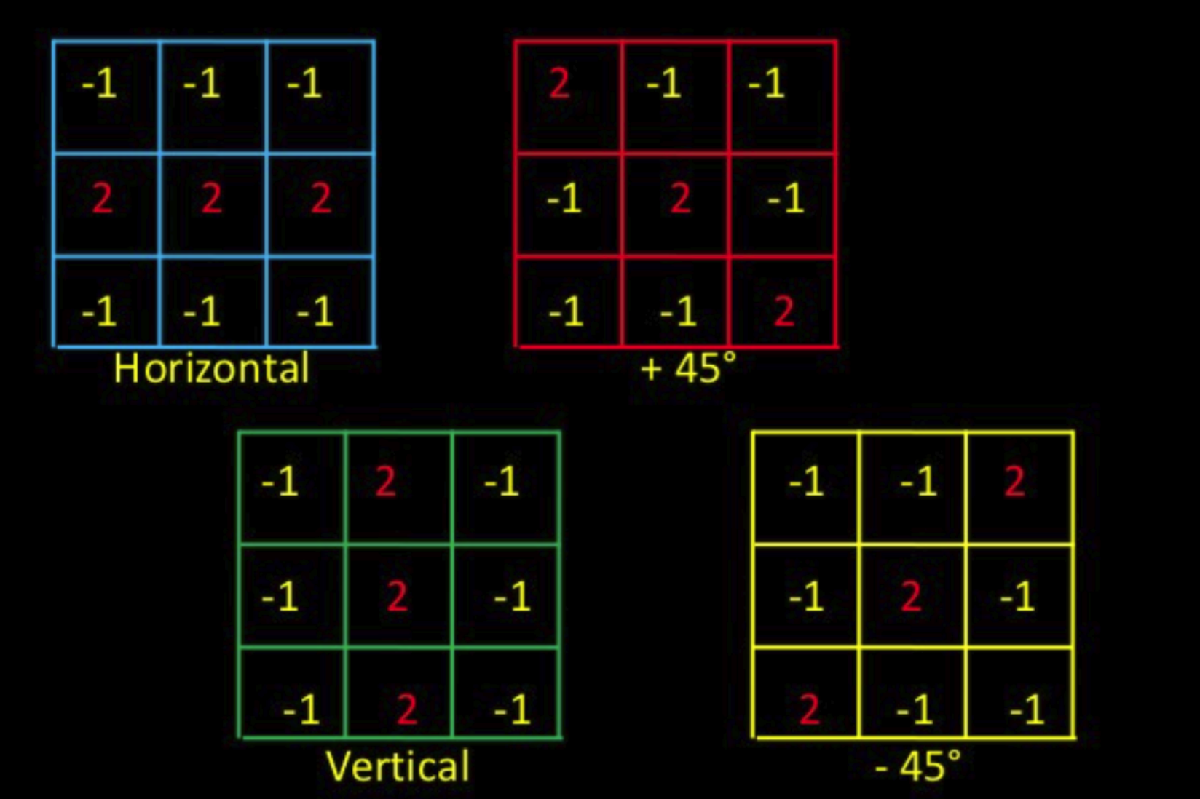

To find all the line (one pixel thick) oriented at 45°

clear
close all
f=imread('forme.tif');
W = [2 -1 -1; -1 2 -1; -1 -1 2]
g=imfilter(double(f), W);
imshow(g);
g=abs(g);
M=max(g(:));  T=0.6;
g=g >= T*M;
imshow(g)

**Matlab Edge detection function**

[`BW`](https://it.mathworks.com/help/releases/R2024b/images/ref/edge.html?searchHighlight=edge&s_tid=doc_srchtitle#buo5g3w-1-BW)` = edge(`[`I`](https://it.mathworks.com/help/releases/R2024b/images/ref/edge.html?searchHighlight=edge&s_tid=doc_srchtitle#buo5g3w-1-I)`,`[`method`](https://it.mathworks.com/help/releases/R2024b/images/ref/edge.html?searchHighlight=edge&s_tid=doc_srchtitle#d126e107373)`,`[`threshold`](https://it.mathworks.com/help/releases/R2024b/images/ref/edge.html?searchHighlight=edge&s_tid=doc_srchtitle#buo5g3w-1-threshold)`,`[`direction`](https://it.mathworks.com/help/releases/R2024b/images/ref/edge.html?searchHighlight=edge&s_tid=doc_srchtitle#buo5g3w-1-direction)`)`

[g,t]= edge(f, ‘sobel’, dir);

dir = ‘horizontal’, ‘vertical’, ‘both’

[g,t]= edge(f, ‘prewitt’, dir);

[g,t]= edge(f, ‘roberts’, dir);

[g,t]= edge(f, ‘log’, sigma);

[g,t]= edge(f, ‘canny’, dir);

`edge` ignores all edges that are not stronger than `threshold`

clear
close all
a=imread('Fig1016.tif');
[g,t]= edge(a, 'sobel', 'vertical');
subplot(1,2,1)
imshow(g)
% to remove weaker edge
g= edge(a, 'sobel', 0.15, 'vertical');
subplot(1,2,2)
imshow(g)

function edge do not compute Sobel edge at  45°

we have to use a mask

w45=[2 -1 -1; -1 2 -1; -1 -1 2]

clear
close all
a=imread('Fig1016.tif');
w45=[2 -1 -1;-1 2 -1;-1 -1 2];
g45= imfilter(double(a), w45, 'replicate');
T = 0.40*max(abs(g45(:)));
g45 = g45 >= T;
imshow(g45)

**Roberts** operator designed to respond maximally to edges running at 45° 

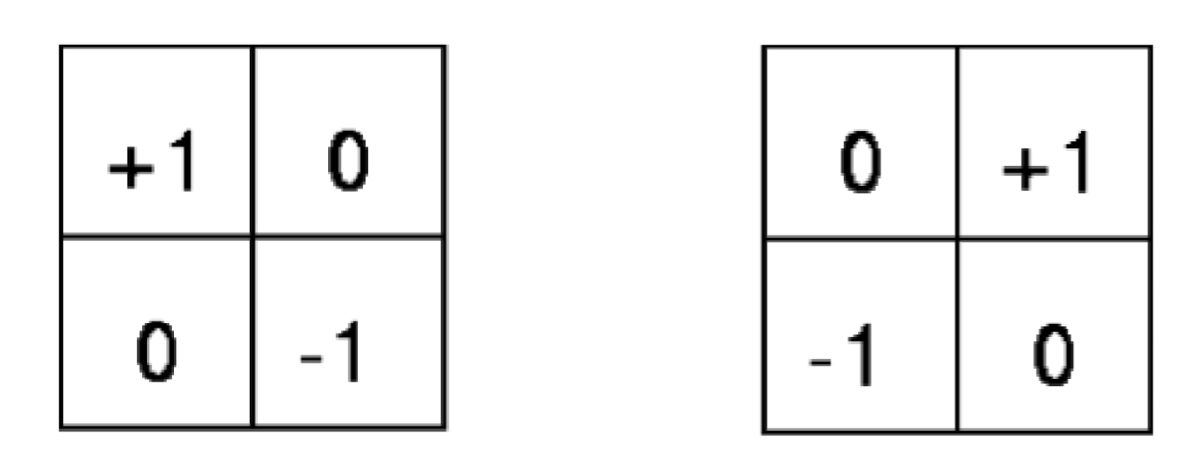

[g,t]= edge(f, ‘roberts’, dir);

the 'horizontal' direction actually detects edges at an angle of 135° from horizontal, and the 'vertical' direction detects edges at an angle of 45° from horizontal.

clear
close all
a=imread('Fig1016.tif');
[g,t]= edge(a, 'roberts', 'vertical');
subplot(1,2,1)
imshow(g)
g= edge(a, 'roberts', 0.1, 'vertical');
subplot(1,2,2)
imshow(g)

**Canny: the optimal detector**

**Low error rate**: Meaning a good detection of only existent edges.

**Good localization**: The distance between edge pixels detected and real edge pixels have to be minimized.

**Minimal response**: Only one detector response per edge (edge in the image should only be marked once)

**The image is smoothed by Gaussian convolution** (Filter out any noise). Large  sigma to detect large scale edges, small  sigma   to detect fine features

**Find the intensity gradient** of the image

**Edge thinning **by** Non-maximal suppression**

**Thresholding  (Hysteresis): **Canny uses two thresholds (upper and lower)

If a pixel gradient is higher than the upper threshold, the pixel is accepted as an edge (strong edge)

If a pixel gradient value is below the lower threshold, then it is rejected.

If the pixel gradient is between the two thresholds it is a weak edge.

**Usually a weak edge pixel caused from true edges is connected to a strong edge pixel** while weak edge caused by noise are unconnected.

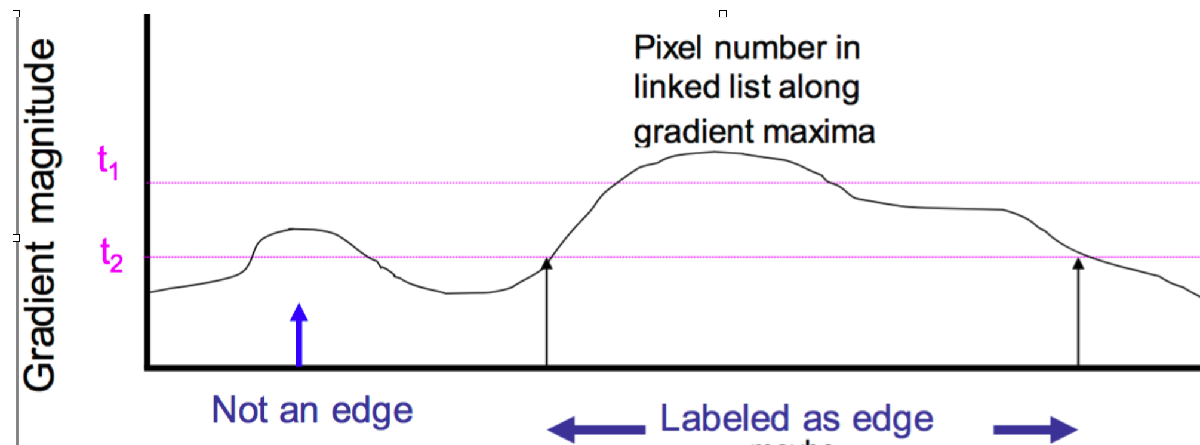

The two threshold values are empirically determined values

The low threshold is typically set to 1/2 of the high threshold

**BW = edge(I,'Canny',threshold,sigma) **

clear
close all
I = imread('circuit.tif');
imshow(I)
BW1 = edge(I,'Canny');
BW2 = edge(I,'Prewitt');
figure
imshowpair(BW1,BW2,'montage')
title('Canny vs Prewit')

Exercise:

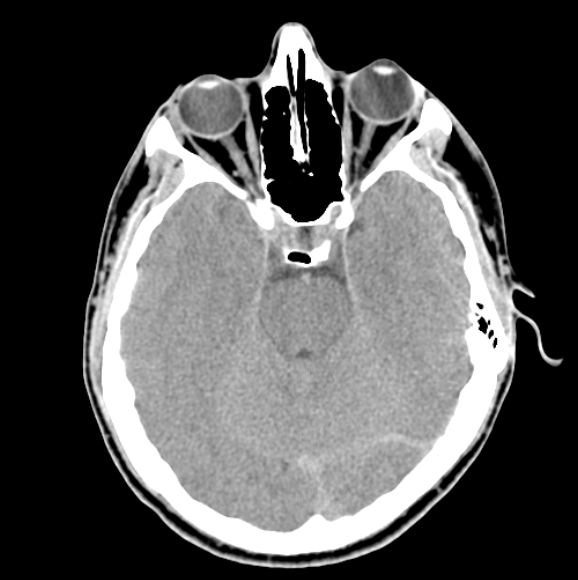

**Extract** the edges of **the outer contour of the brain** (the gray region in the image), **the contour of the spinal region** (shown directly behind the nose, toward the front of the brain), and **the outer contour of the head**. 

**Generate the thinnest, continuous contours possible**, while eliminating edge details related to the gray content in the eyes and brain areas. 

clear 
close all
a=imread('headCT.tif');
% default Canny
[ac,T] = edge(a,'canny');
t=sprintf('threshold = %f ',T);
disp(t)
figure 
subplot(2,2,1)
imshow(ac)
colormap(gray(255))
title('default canny')
% laplacian of a gaussian
ap=edge(a,'log'); 
subplot(2,2,2)
imshow(ap)
colormap(gray(256))
title('laplacian of gaussian')
% gaussian and gradient (Prewitt) 
ag=imgaussfilt(a);
[Gmag, Gdir] = imgradient(ag,'prewitt');
m=max(Gmag(:));
G=Gmag>0.15*m;
subplot(2,2,3)
imshow(G)
colormap(gray(256))
title('gaussian-gradient threshold')
% Canny Th=0.15 and sigma = 2  
ac = edge(a,'canny',0.15,2);
subplot(2,2,4)
imshow(ac)
colormap(gray(255))
title(' canny w threshold 0.15 S 2')